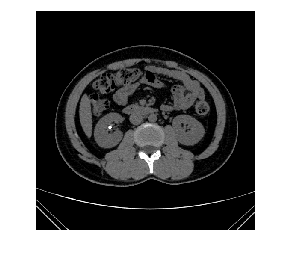

% Read the desired image
I = imread('Stone- (1000).jpeg');
imshow(I);

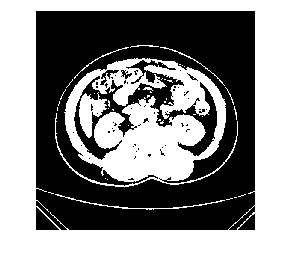


% Convert the image to grayscale
I = rgb2gray(I);

% Create a binary image of only the grey and white pixels
binaryI = I>40;
imshow(binaryI)

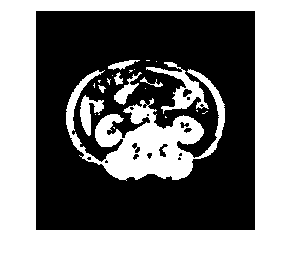


% Erode the image to eliminate artifacts
seD = strel('sphere',3);
binaryI = imerode(binaryI,seD);
imshow(binaryI)

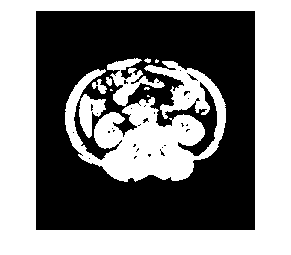


% Dilate the image to bring back kidney size
binaryI = imdilate(binaryI,seD);
imshow(binaryI)

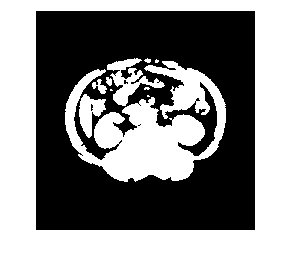


%fill in holes
binaryI = imfill(binaryI, 'holes');
imshow(binaryI)


% Get region properties
stats = regionprops(binaryI, 'Area')

stats = 13×1 struct array with fields:
    Area


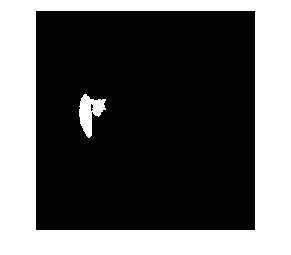


% Get the maximum area from the region
cell = struct2cell(stats);
M = cell2mat(cell);
maxvalue = max(M);

% Declare the area range you want to keep and not filter
if maxvalue >= 20000 && maxvalue < 25000
    minArea = 2800;
    maxArea = 3600;
elseif maxvalue >= 25000 && maxvalue < 50000
    minArea = 3500;
    maxArea = 5000;
elseif maxvalue >= 50000
    minArea = 2500;
    maxArea = 4000;
else
    minArea = 2000;
    maxArea = 3200;
end

% Add label to each connected object 
labels = bwlabel(binaryI);

% Filter based on area range checks for each one that they fit inside the
% area
binaryI = ismember(labels, find([stats.Area] >= minArea & [stats.Area] <= maxArea));
imshow(binaryI)

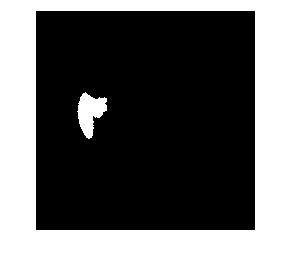


% Dilate the kidneys to ensure kidney stone capture
binaryI = imdilate(binaryI,seD);
imshow(binaryI)

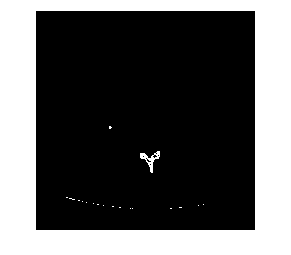


% Binarize original image to isolate anything bright white
whiteI = I > 250;
imshow(whiteI);

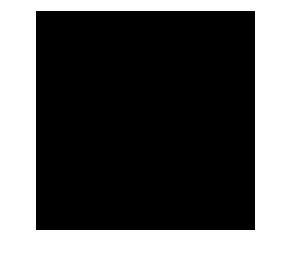


% Compare if kidney stones are in the same location as kindeys
Final = whiteI.*binaryI;
imshow(Final)


% Overlay the mask of kidey stones onto original image
finalOverlay = labeloverlay(I, Final);
imshow(finalOverlay)